# **MATLAB Workshop - 11/30/2018**

**Márcio Duarte Albasini Mourão**

**Materials for this session can be found here: https://marcio-mourao.github.io**

## MATLAB (MATrix LABoratory) is a high-level programming language and interactive environment for algorithm development, data visualization, data analysis, and numeric computation. Core strengths of the system include rapid development, powerful built-in functionality and extensive application-specific functionality provided by both official toolboxes and user-contributed code.

## MATLAB contains several different parts:

- **Desktop Tools and Development Environment** **-** This part of MATLAB is the set of tools and facilities that help you use and become more productive with MATLAB functions and files. Many of these tools are graphical user interfaces. It includes: the MATLAB desktop and Command Window, an editor and debugger, a code analyzer, and browsers for viewing help, the workspace, and folders.

- **Mathematical Function Library -** This library is a vast collection of computational algorithms ranging from elementary functions, like sum, sine, cosine, and complex arithmetic, to more sophisticated functions like matrix inverse, matrix eigenvalues, and fast Fourier transforms.

- **The Language -** The MATLAB language is a high-level matrix/array language with control flow statements, functions, data structures, input/output, and object-oriented programming features. It allows both "programming in the small" to rapidly create quick programs you do not intend to reuse. You can also do "programming in the large" to create complex application programs intended for reuse.

- **Graphics -** MATLAB has extensive facilities for displaying vectors and matrices as graphs, as well as annotating and printing these graphs. It includes high-level functions for two-dimensional and three-dimensional data visualization, image processing, animation, and presentation graphics. It also includes low-level functions that allow you to fully customize the appearance of graphics as well as to build complete graphical user interfaces on your MATLAB applications.

- **External Interfaces -** The external interfaces library allows you to write C and Fortran programs that interact with MATLAB. It includes facilities for calling routines from MATLAB (dynamic linking), for calling MATLAB as a computational engine, and for reading and writing MAT-files.

# **References**

## **A MATLAB Tutorial -  **[https://people.math.osu.edu/overman.2/matlab.pdf](https://people.math.osu.edu/overman.2/matlab.pdf)

## **        Ed Overman, Department of Mathematics, The Ohio State University**

## **Introduction to MATLAB for engineering students - **[http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf](http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf)

## **       David Houcque, Northwestern University**

## **Mathworks - **[http://mathworks.com ](http://mathworks.com )

# **Summary**

- **Desktop tools and development environment**

- **Variables**

- **Definitions and Matlab data types**

- **Vectors and Matrices**

- **Script M-files and Functions**

- **Reading from and writing data to binary MATLAB files**

- **Control flow operators**

- **Data visualization**

# **Desktop tools and Development Environment**

# 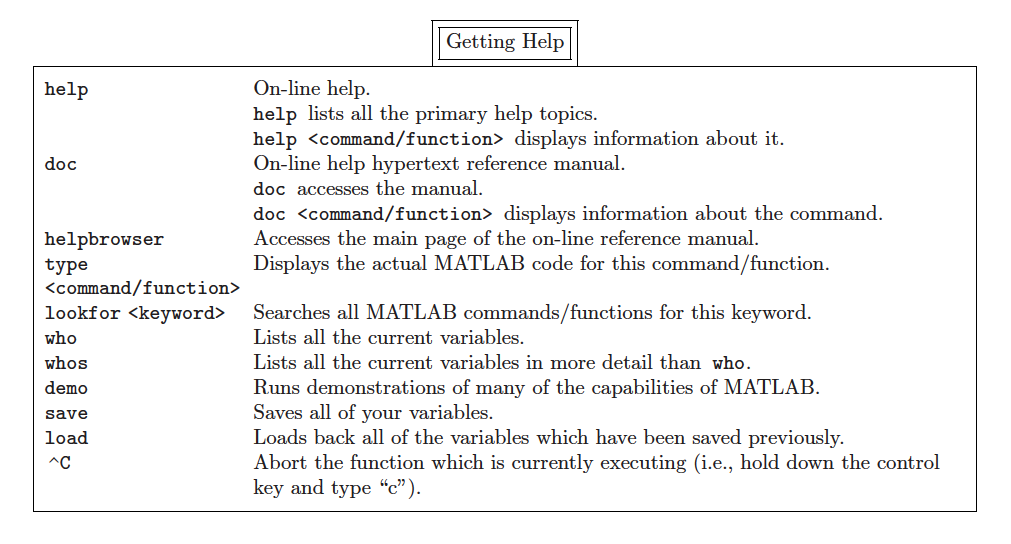

demo % access Matlab's demonstration page

help plot % obtain help in the command window

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

doc plot % access the online browser in reference to the plot command

%lookfor knn % obtain all potential Matlab functions associated with 'knn

a = 5

a = 5

who % display existing workspace variables 


Your variables are:

a  



whos % the same as who but display additional information

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              



clc % clears the screen

# **Variables**

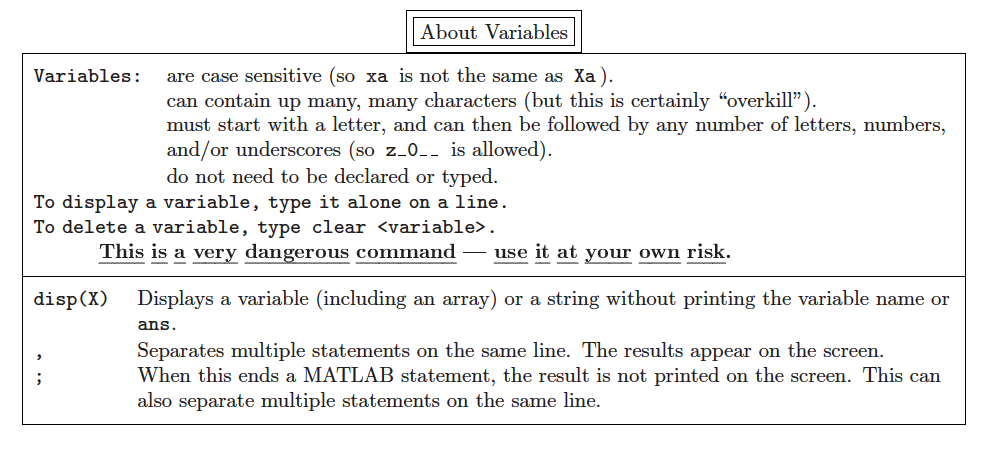

There are reserved names/words, called keywords:

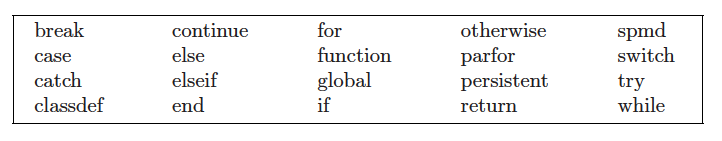

...as well as predefined variables:

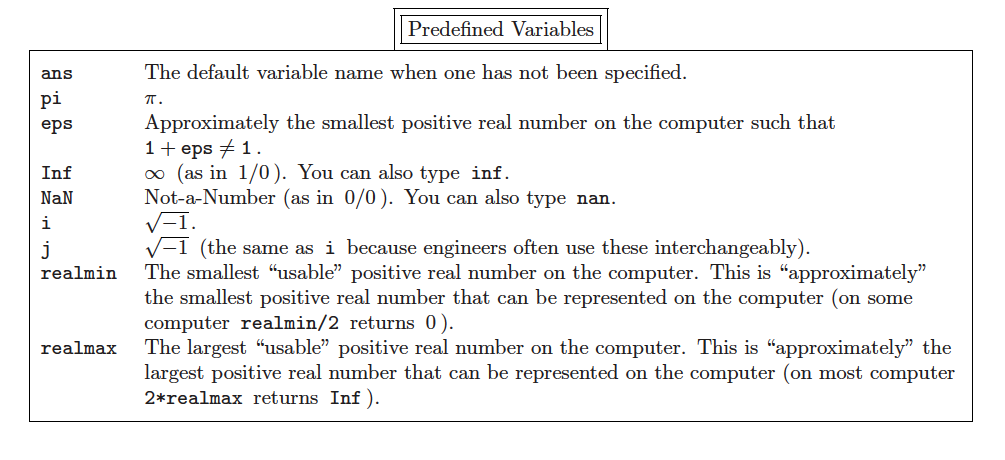

x = 2 % assigns variable x to 2

x = 2

x

x = 2

x; % semicolon supresses the output

fx = 3*x^6 - 17*x^3+79 % Matlab evaluates x in the expression on the right and assigns the outcome value to a new variable fx

fx = 135

x = 2^(1/3); fx = 3*x^6 - 17*x^3 + 79; g = 3/fx; % makes three assignments to variables in one single line of code (this is not very good for readibility)

x = 2^(1/3), fx = 3*x^6 - 17*x^3 + 79, g = 3/fx

x = 1.2599

fx = 57

g = 0.0526

x = x+5 % adds 5 to the value of x and updates x

x = 6.2599

x

x = 6.2599

clear % clears the workspace

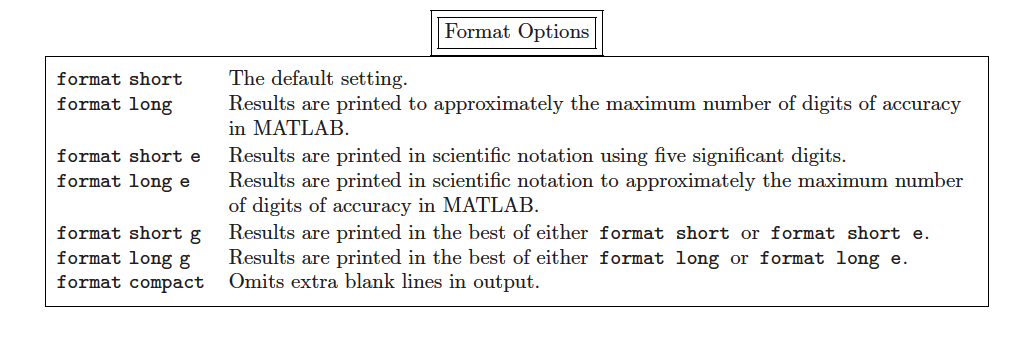

a=1/3

a = 0.3333

format long % changes the display format to maximum precision (values do not actualy change, just how they are displayed)

a

a =    0.333333333333333


format short

a

a = 0.3333

# **Definitions: Matrices and Vectors**

- `The most basic MATLAB data structure is the matrix: a two-dimensional, rectangular structure capable of storing multiple elements of data in an easily accessible format.`

- `The elements of a matrix must all be of the same data type (numeric, character, logical etc.), but here we will focus on numeric matrices.`

- `MATLAB uses two-dimensional matrices to store single elements and linear series of elements as well. In these cases, the dimensions are 1-by-1 and 1-by-N (or N-by-1) respectively. For numeric data, special meaning is sometimes attached to 1-by-1 matrices, which are scalars, and to matrices with only one row or column, which are vectors.`

- `MATLAB also supports data structures that have more than two dimensions. These data structures are referred to as multidimensional arrays, and indeed the matrix is really a special case of an n-dimension array, with n=2.`

# **MATLAB data types**

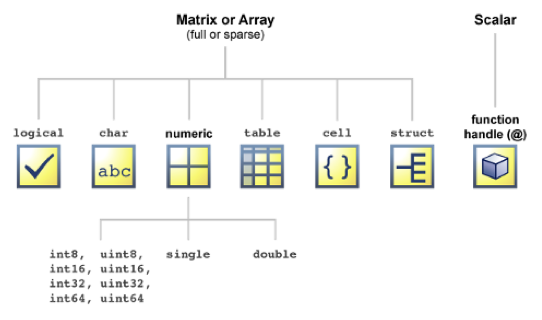

[http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html](http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)

# **Vectors**

clear

who

x=[3 2 4 7 5] % creates a row vector x with 5 elements

x =      3     2     4     7     5


x=[3,2,4,7,5] % creates a row vector x with 5 elements 

x =      3     2     4     7     5


y=[3;2;4;7;5] % creates a column vector y with 5 elements

y =      3
     2
     4
     7
     5


x(1) % access the first element of the vector

ans = 3

x(0) 

Array indices must be positive integers or logical values.

x(6)

Index exceeds the number of array elements (5).

x(3)

ans = 4

y=1:5 % creates a row vector y with 5 elements from 1 to 5

y =      1     2     3     4     5


y=1:5'

y =      1     2     3     4     5


y=(1:5)' % ' is used to transpose the vector y - creates a column vector

y =      1
     2
     3
     4
     5


x=1:2:10 % creates a row vector with every other elemens from 1 to 10

x =      1     3     5     7     9


x1=linspace(1,10,5) % creates a vector with 5 elements from 1 to 10

x1 =     1.0000    3.2500    5.5000    7.7500   10.0000


y1=x1(3:4) % slices vector x1 to obtain the third and fourth elements of x1 and assigns to y1

y1 =     5.5000    7.7500


y1(2)=3 % modifies the second value of y1 to 3

y1 =     5.5000    3.0000


x1 % no modification occurs in x1

x1 =     1.0000    3.2500    5.5000    7.7500   10.0000


y1(5)=4

y1 =     5.5000    3.0000         0         0    4.0000


x=[3 5]

x =      3     5


x=[x x] % concatenates vector x with vector x 

x =      3     5     3     5


x=1:5

x =      1     2     3     4     5


x+x % sums vectors, add elements at the same index on both vectors

ans =      2     4     6     8    10


x=x+x

x =      2     4     6     8    10


x=1:5

x =      1     2     3     4     5


x=x*0.5 % multiply each element of the vector by 1/2

x =     0.5000    1.0000    1.5000    2.0000    2.5000


y=1:5

y =      1     2     3     4     5


x+y

ans =     1.5000    3.0000    4.5000    6.0000    7.5000


x*y

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

x.*y % multiply each element of the vectors x and y

ans =     0.5000    2.0000    4.5000    8.0000   12.5000


x*y' % obtains a scalar, product of the two vectors

ans = 27.5000

x=10:-2:0 % creates a vector from 10 to 0 with a negative step of -2

x =     10     8     6     4     2     0


x=7:4 % this should produce an empty vector since the step = 1 by default


x =

  1×0 empty double row vector



x=1:10

x =      1     2     3     4     5     6     7     8     9    10


max(x) % obtains maximum value of the vector

ans = 10

min(x) % obtains minimum value 

ans = 1

sum(x) % obtains the sum of the values 

ans = 55

prod(x) % obtains the product of elements 

ans = 3628800

mean(x) % obtains the mean 

ans = 5.5000

std(x) % obtains the standard deviation

ans = 3.0277

x=[1 23 5 17 8 3]

x =      1    23     5    17     8     3


x<4 % evaluates this condition for each element of vector x, it returns a boolean index of the same length as vector x

ans = 1×6 logical array
   1   0   0   0   0   1


x(x<4) % gets values x lower than 4

ans =      1     3


# **Matrices**

clear

who

[7 -2 +5], [7 - 2 + 5], [7, - 2, +5]

ans =      7    -2     5


ans = 10

ans =      7    -2     5


A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1] % creates a 4 by 4 matrix with the specified elements, use semicolon for a new line

A =      6     3     2     8
     5     1     3     7
     1     6     7     2
     4     5     4     1


B = [6 3 2 8; 5 1 3]

Dimensions of arrays being concatenated are not consistent.

ones(2,5) % creates a matrix of ones with 2 lines and 5 columns

ans =      1     1     1     1     1
     1     1     1     1     1


zeros(2,2) % creates a matrix of zeros with 2 lines and 2 columns

ans =      0     0
     0     0


rand(2,2) % creates a 2x2 matrix with random uniform numbers from 0 to 1

ans =     0.8147    0.1270
    0.9058    0.9134


A = [1 2;3 4]

A =      1     2
     3     4


B = [5 6;7 8]

B =      5     6
     7     8


A+B % sums the two matrices

ans =      6     8
    10    12


A-B

ans =     -4    -4
    -4    -4


C=[A,B] % concatenates horizontaly the two matrices

C =      1     2     5     6
     3     4     7     8


D=[A;B] % concatenates vertically the two matrices

D =      1     2
     3     4
     5     6
     7     8


B = [5 6;7 8;9 10]

B =      5     6
     7     8
     9    10


C=[A,B]

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

D=[A;B]

D =      1     2
     3     4
     5     6
     7     8
     9    10


A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]

A =      6     3     2     8
     5     1     3     7
     1     6     7     2
     4     5     4     1


A(3,2) % obtains the value of matrix A in the third line, second column

ans = 6

A(7) % obtain the same value of matrix A using linear indexing

ans = 6

linearindex = sub2ind(size(A),3,2) % obtain the linear indexing from the line/column indexing

linearindex = 7

[X,Y] = ind2sub(size(A),5) % obtain the line/column indexing from the linear indexing

X = 1

Y = 2

A(2,:) % obtains the entire second line of matrix A

ans =      5     1     3     7


A(1:3:16)

ans =      6     4     6     3     8     1


A(2:3,1:3)

ans =      5     1     3
     1     6     7


A(2,2:end)

ans =      1     3     7


A([1,4,9])

ans =      6     4     2


L = A<5 % evaluates the condition for each element of matrix A

L = 4×4 logical array
   0   1   1   0
   0   1   1   0
   1   0   0   1
   1   0   1   1


A(L) % obtains values of A lower than 5

ans =      1
     4
     3
     1
     2
     3
     4
     2
     1


A(A<5)

ans =      1
     4
     3
     1
     2
     3
     4
     2
     1


A(A<5) = 0 % assigns all values lower than 5 to 0 in matrix A

A =      6     0     0     8
     5     0     0     7
     0     6     7     0
     0     5     0     0


size(A)

ans =      4     4


length(A)

ans = 4

numel(A)

ans = 16

islogical(A) % checks whether A is a matrix of logical values

ans = logical
   0


isnumeric(A) % checks whether A is a matrix of numeric values

ans = logical
   1


isvector(A)

ans = logical
   0


isscalar(A)

ans = logical
   0


ismatrix(A)

ans = logical
   1


isempty(A)

ans = logical
   0


F = [1,2,3;4,5,6]

F =      1     2     3
     4     5     6


F(1,5)

Index in position 2 exceeds array bounds (must not exceed 3).

F(1,5)=3

F =      1     2     3     0     3
     4     5     6     0     0


F = [1,2,3;4,5,6]

F =      1     2     3
     4     5     6


F(1:2,5:6) = 8

F =      1     2     3     0     8     8
     4     5     6     0     8     8


F(:,6) = [] % removes the sixth colum of matrix F

F =      1     2     3     0     8
     4     5     6     0     8


F = [1,2,3;4,5,6]

F =      1     2     3
     4     5     6


transpose(F) % tranposes matrix F

ans =      1     4
     2     5
     3     6


reshape(F,1,6) % reshapes matrix F into a matrix with 1 lines and 6 columns

ans =      1     4     2     5     3     6


A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]

A =      6     3     2     8
     5     1     3     7
     1     6     7     2
     4     5     4     1


sort(A,1) % sort matrix A along the first dimension

ans =      1     1     2     1
     4     3     3     2
     5     5     4     7
     6     6     7     8


sort(A,2) % sort matrix A along the second dimension

ans =      2     3     6     8
     1     3     5     7
     1     2     6     7
     1     4     4     5


sort(A,2,'descend') % sort matrix A along the second dimension, from the highest to the lowest value

ans =      8     6     3     2
     7     5     3     1
     7     6     2     1
     5     4     4     1


sortrows(A,2) % sort the matrix A according to the second column, maintaining dependence between columns of the matrix

ans =      5     1     3     7
     6     3     2     8
     4     5     4     1
     1     6     7     2


max(A)

ans =      6     6     7     8


max(A,[],2) % obtains the maximum value of each line of matrix A 

ans =      8
     7
     7
     5


[y,I]=max(A,[],2) % obtains the maximum values of matrix A in y and the indexes on I

y =      8
     7
     7
     5


I =      4
     4
     3
     2


mean(A,1) % obtains mean along the first dimension (number of columns is invariant)

ans =     4.0000    3.7500    4.0000    4.5000


mean(A,2) % obtains mean along the second dimension (number of lines is invariant)

ans =     4.7500
    4.0000
    4.0000
    3.5000


stand_A=(A-mean(A,1))./std(A,1) % standardize A

stand_A =     1.0690   -0.3906   -1.0690    1.1508
    0.5345   -1.4321   -0.5345    0.8220
   -1.6036    1.1717    1.6036   -0.8220
         0    0.6509         0   -1.1508


mean(stand_A) % Obtain mean

ans = 	1.0e+-16 *

         0    0.2776         0         0


## **There are many more operations on matrices. Here are a few of them:**

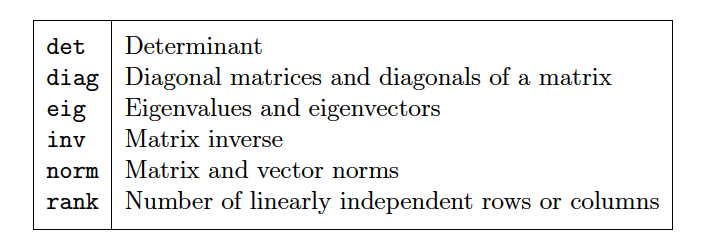

# **Script M-files**

edit workshop.m % open Matlab's editor (include any commands in the file and save it)

workshop % run the script file (the extension is not included)

- The name of the file includes the extension ".m", i.e., "<file name>.m", but you execute it in MATLAB by typing <file name>, i.e., without the extension.

- The file name can consist of (almost any number of) letters (lowercase and/or uppercase), numbers, and underscores, i.e. "_".

- The first character must be a letter.

- Spaces are not allowed.

- Make sure your file name is not the same as one of MATLAB's commands/functions.

type workshop % displays the content of the file

# **Functions**

## **Functions are programs (or routines) that accept input arguments and return output arguments. Each M-file function (or function or M-file for short) has its own area of workspace, separated from the MATLAB base workspace.**

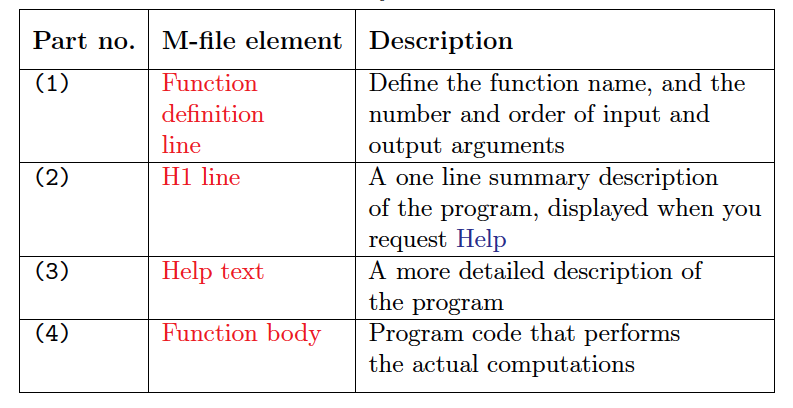

**function [outputs] = function_name(inputs)**

**    %comments    **

**    body**

**end**

**Examples of headers:**

-     function C=FtoC(F)

-     function area=TrapArea(a,b,h)

-     function [h,d]=motion(v,angle)

## **Scripts vs Functions**

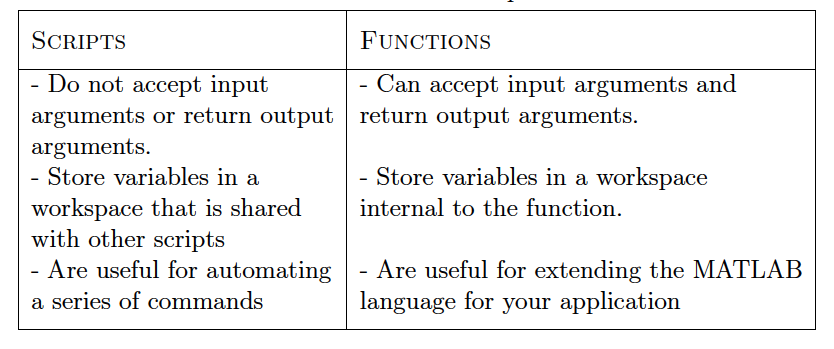

## **Lets define a function that calculates the factorial of a number n!**

# **Reading from and writing data to MATLAB binary files (MAT-files)**

MAT-files are the default data storage file type in MATLAB. They are binary files that can store the variables in your current workspace for later use. MAT files use the .mat extension. In common with many MATLAB built-in functions, **load** and **save **can be called in two different ways: 1) using spaces between the function name and arguments; 2) using function syntax.

clear

x = 2

x = 2

y = 5

y = 5

save('vars','x','y')

x = 5000

x = 5000

load('vars')

whos -file vars

  Name      Size            Bytes  Class     Attributes

  x         1x1                 8  double              
  y         1x1                 8  double              



# **Control flow and operators**

**MATLAB is also a programming language. Like other computer programming languages, MATLAB has some decision making structures for control of command execution. These decision making or control flow structures include for loops, while loops, and if-else-end constructions. Control flow structures are often used in script M-files and function M-files.**

**MATLAB has three main control flow structures: the if statement, the for loop and the while loop.**

## **The ``if...end'' structure**

**if ... end**

**if ... else ... end**

**if ... elseif ... else ... end**

**The simplest form of the if statement is: **

**if expression**

**    statements**

**end**

**Examples**

a=2;b=4;c=2;
discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
end

discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
else
    disp('Roots are real, but may be repeated')
end

Roots are real, but may be repeated


discr = b*b - 4*a*c;
if discr < 0
    disp('Warning: discriminant is negative, roots are imaginary');
elseif discr == 0
    disp('Discriminant is zero, roots are repeated')
else
    disp('Roots are real')
end

Discriminant is zero, roots are repeated


**Notes:**

- **elseif has no space between else and if (one word)**

- **no semicolon (;) is needed at the end of lines containing if, else, end**

- **indentation of if block is not required, but facilitate the reading**

- **the end statement is required**

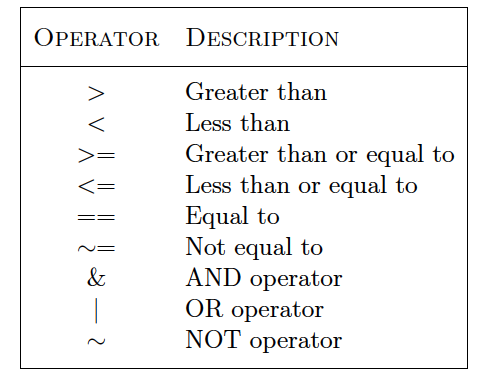

## The ``for...end'' loop

for variable = expression

    statements

end

**Examples:**

for i=1:5
    x=i*i
end

x = 1

x = 4

x = 9

x = 16

x = 25

n=5;
out=n;
for i=n-1:-1:2
    out=out*i;
end
disp(out)

   120



## The ``while...end'' loop

while expression

    statements

end

**Example:**

x = 1;
while x <= 10
    x = 3*x
end

x = 3

x = 9

x = 27

**Others: **

- The **break** statement**. **A while loop can be terminated with the break statement, which passes control to the first statement after the corresponding end. The break statement can also be used to exit a for loop.

- The **continue** statement can also be used to exit a for loop to pass immediately to the next iteration of the loop, skipping the remaining statements in the loop.

- Other control statements include **return**, etc..

# **Data Visualization**

## Figures, Axes and Graphs

-  A figure is a MATLAB window used for graphical display.

-  An axes is a 2D or 3D data space defined within a figure.

-  A plot is any graphic display you can create within a figure window. 

-  Figures can contain any number of plots.

-  A graph is a plot of data within an axes.

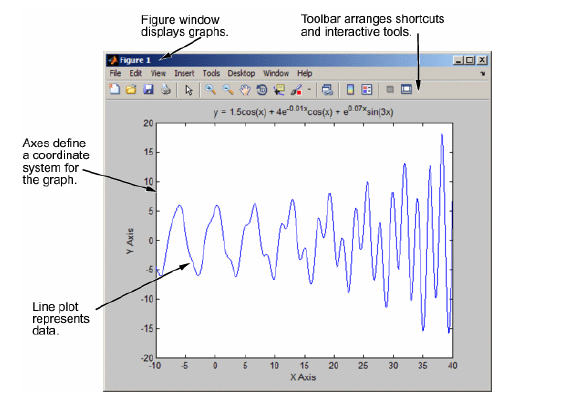

## Plotting Functions

[http://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html](http://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

## Line Graphs: plot

The basic MATLAB graphing procedure, for example in 2D, is to take a vector of x-coordinates, x = (x1; ... ; xN), and a vector of y-coordinates, y = (y1; ... ; yN), locate the points (xi; yi), with i = 1; 2; ... ; n and then join them by straight lines. You need to prepare x and y in an identical array form; namely, x and y are both row arrays or column arrays of the same length.

clear
close all
figure(1) % creates new figure

% Set variables for the x and y axis of the plot
x = 0:pi/10:2*pi;
y1 = 2*cos(x);
y2 = cos(x);
y3 = 0.5*cos(x);

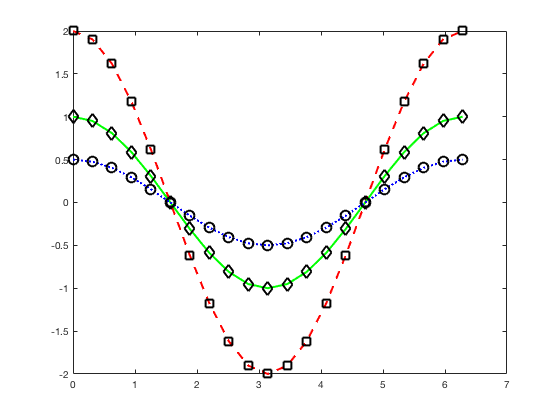

% Plot
plot(x,y1,'--rs',x,y2,'-gd',x,y3,':bo',...
       'LineWidth',2,...
       'MarkerEdgeColor','k',...
       'MarkerSize',10)

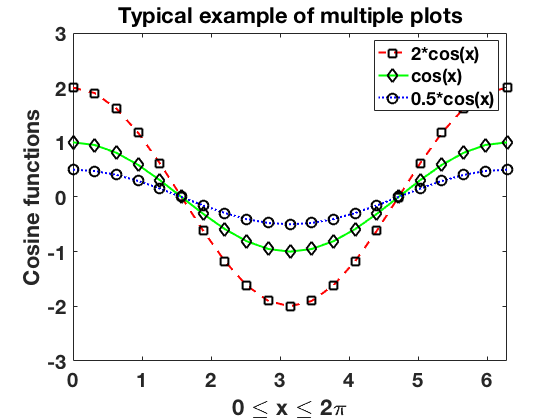

set(gca,'FontWeight','bold','FontSize',20)
xlabel('0 \leq x \leq 2\pi')
ylabel('Cosine functions')
legend('2*cos(x)','cos(x)','0.5*cos(x)')
title('Typical example of multiple plots')
axis([0 2*pi -3 3])

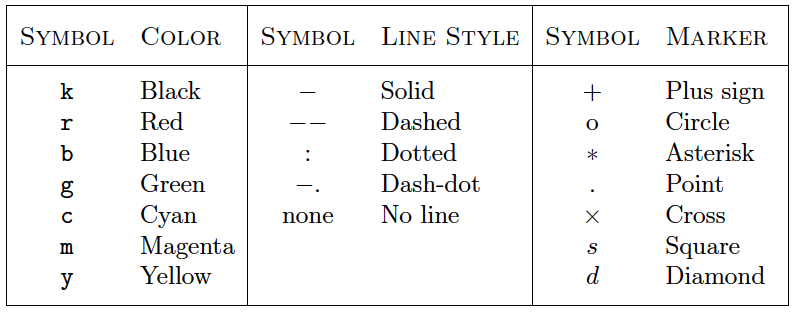

close all

## **3D Example**

The function plot3 is the same as the plot function, but in three dimensions. In addition to this standard three dimensional plot, we can also create surfaces and contour plots.

clear
close all

% Create x and y variables for plot
x=linspace(-2,2);
y=linspace(-5,5);

% Define array of values so to obtain Z
[X,Y]= meshgrid(x,y);

% Define Z as a function of X and Y
Z=Y./(1+X.^2+Y.^2);

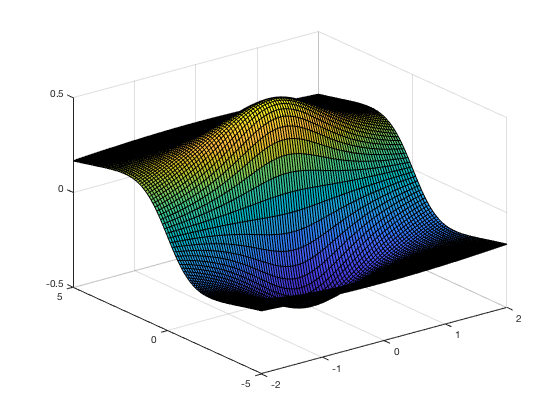

% Plots the surface
surf(X,Y,Z)

## **4D Example**

load accidents hwydata                             % load data

long = -hwydata(:,2);                              % longitude data
lat = hwydata(:,3);                                % latitude data
rural = 100 - hwydata(:,17);                       % percent rural data
fatalities = hwydata(:,11);                        % fatalities data

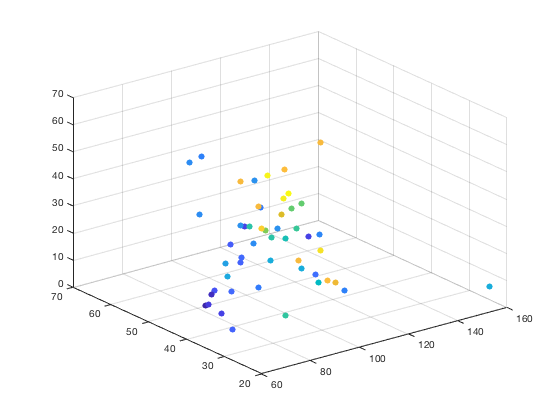

scatter3(long,lat,rural,40,fatalities,'filled')    % draw the scatter plot

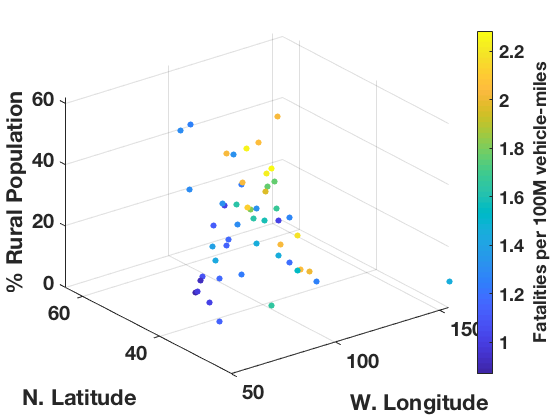

% Set fonts and labels for the plot
set(gca,'FontWeight','bold','FontSize',20)
xlabel('W. Longitude')
ylabel('N. Latitude')
zlabel('% Rural Population')
cb = colorbar; % create and label the colorbar
cb.Label.String = 'Fatalities per 100M vehicle-miles';